# Using APIs to Automatically Download Meteorological and Oceanographic Data from NOAA/NDBC using MATLAB®

By

George Voulgaris, SEOE, UofSC

Email: gvoulgaris@geol.sc.edu

## 1. Introduction

This goals of this Live Script is to teach the user the following tasks:

• How to import relevant data directly from the federal agencies (NOAA/NDBC) into MATLAB for subsequent analysis

• Automate data download and analysis.

• Create functions and plots specific to the analysis required for these data 

• Create date formatted labels for plots.

## 2. Data available at NOAA/NDBC

NOAA's homepage: [NOAA / NDBC](https://www.ndbc.noaa.gov/) provides oceanographic data for a variety of locations around the globe.

The data provided are clacified as "***Historical***" and "***Recent***" with the former indicating QA/QC-ed time series. Each station has a unique identification number.

A comprehensive list of the historical data by station ID and year is available at: [https://www.ndbc.noaa.gov/historical_data.shtml](https://www.ndbc.noaa.gov/historical_data.shtml)

NDBC historical data contain data for each station (if available) from the beginning of year to the end  These files are text files stored in a compressed (gzipped) format. The types of data available are (links below take you to the relevant data inventory lists)

- [Standard Meteorological](https://www.ndbc.noaa.gov/historical_data.shtml#stdmet)

- [Continous Winds](https://www.ndbc.noaa.gov/historical_data.shtml#cwind)

- [Ocean Current Data](https://www.ndbc.noaa.gov/historical_data.shtml#adcp)

- [Oceanographic Data](https://www.ndbc.noaa.gov/historical_data.shtml#ocean)

- [Spectral wave density](https://www.ndbc.noaa.gov/historical_data.shtml#swden) (Non directional wave energy spectra)

-     [Spectral wave (alpha1) direction data](https://www.ndbc.noaa.gov/historical_data.shtml#swdir) (used to create directional wave spectra)

-     [Spectral wave (alpha2) direction data](https://www.ndbc.noaa.gov/historical_data.shtml#swdir2) (used to create directional wave spectra)

-     [Spectral wave (r1) direction data](https://www.ndbc.noaa.gov/historical_data.shtml#swr1) (used to create directional wave spectra)

-     [Spectral wave (r2) direction data](https://www.ndbc.noaa.gov/historical_data.shtml#swr2) (used to create directional wave spectra)

- [Water-column Height (Tsunameters using DART® technology)](https://www.ndbc.noaa.gov/historical_data.shtml#dart)

- [Water Level](https://www.ndbc.noaa.gov/historical_data.shtml#wlevel)

## 3. Downloading NOAA/NDBC Historical Data into MATLAB®

There are two methods of downloading NDBC data: (1) download as a gzip compressed file; and (2) view and download the file as a text file. 

In here we will learn how to download the text file data directly from the web to our MATLAB® environment. 

### 3.1 Hyperlink pattern for data download

Before we start we better clear the MATLAB® workspace and close all figures

clearvars
close all

The first step would be to identify the pattern for creating the hyperlink to the location of the data. 

All data locations have as root the NDBC API location which we can save as a string in parameter NOAANDBC

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=')

NOAANDBC = 'https://www.ndbc.noaa.gov/view_text_file.php?filename='

The name of the file (fname) of interest is constructed using information on the **station ID** and **year** historical data is requested together with information on the type of data. The latter is listed in the table below:

## 4. Ocean current data (ADCP data,'a'-'adcp'):

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41008a2009.txt.gz&dir=data/historical/adcp/](https://www.ndbc.noaa.gov/view_text_file.php?filename=41008a2009.txt.gz&dir=data/historical/adcp/)

https://www.ndbc.noaa.gov/view_text_file.php?filename=41008a2009.txt.gz&dir=data%2Fhistorical%2Fadcp%2F

stationID=41008;   % The station ID number
year = 2009;       % The year historical data is required for
data1='a';         % String #1 used in constructing the hyperlink as per NOAA/NDBC
data2='adcp';      % String #2 used for ADCP data as per NOAA/NDBC
% the parameter fname is constructed using the information above and describes the file of interest
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data%2Fhistorical%2F'];
% location is the full hyperlink where the file is located on the NOAA server
location=[NOAANDBC,fname,data2,'%2F']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41008a2009.txt.gz&dir=data%2Fhistorical%2Fadcp%2F'

We need to check if the file exists using 

`if the status code is 'OK' then the file exists and we can download it; otherwise the assumption is made the the file does not exist. However this might be because the site is down or for other reasons. In this case, first check that the file really exists, and if thats the case try to manually see what the r.StatusCode is.`

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);

if the file exists then we provide a name for it to be sved under in our local computer, In the code below the name is constructed using the information that relates to the file (i.e., adcp_stationID_yyyy.txt) - see parameter localname below.  

if strcmp(r.StatusCode,'OK')             % File was found
  localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname   =websave(localname,location);  % downloads the data and saves it in a file
else
  disp('File does not exist') % File was not found, or site is down or internet is down etc.
end

localname = 'adcp_41008_2009.txt'

### 4.1 Importing the ADCP Data

The format used by NOAA for ADCP data is shown below: 

`#YY  MM DD hh mm DEP01 DIR01 SPD01 DEP02 DIR02 SPD02 ... DEP20 DIR20 SPD20`

`#yr  mo dy hr mn     m   deg  cm/s     m   deg  cm/s ...    m   deg  cm/s  `

`2008 01 01 00 00     2   180  10.0     4   190  11.0 ...    6   200   7.0 `

`2008 01 01 12 00     2   150  13.0     4   150  11.0 ...    6   150   9.0`

`....`

`....`

The first two rows are headers while the data start on the third row. Also we note that the values are separated by a space. In this case we should implement the command

where FILENAME is the name of the file, DELIM is the delimiter to be used (space in this case) and NHEADERLINES is the numbe of headers in the file (in the case above 2)

DELIM=' ';  % Delimiter between values
NHEAD=2;    % No of headers
adcpdata = importdata(pname,DELIM,NHEAD); % structure the data are saved in

or it could be written as:

the parameter adcpdata is a structure array that contains 

where the 56 columns correspond the the data shown in the file format example above

time=datenum([adcpdata.data(:,1:5),adcpdata.data(:,1)*0]); % Time in matlab format
z   = adcpdata.data(:,6:3:end);        % Elevation in m
Dir = adcpdata.data(:,7:3:end);        % Direction in degs
Uz  = adcpdata.data(:,8:3:end)/100;    % Current Speed (m/s

## 5. Standard MET data ('h'-'stdmet'):

[https://www.ndbc.noaa.gov/download_data.php?filename=41004h1995.txt.gz&dir=data/historical/stdmet/](https://www.ndbc.noaa.gov/download_data.php?filename=41004h1995.txt.gz&dir=data/historical/stdmet/)

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41004h1995.txt.gz&dir=data/historical/stdmet/](https://www.ndbc.noaa.gov/view_text_file.php?filename=41004h1995.txt.gz&dir=data/historical/stdmet/)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
stationID=41004;   
year = 2010;
data1='h';
data2='stdmet';
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data/historical/'];
location=[NOAANDBC,fname,data2,'/']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41004h2010.txt.gz&dir=data/historical/stdmet/'

`then the data are downloaded to the local working directory`

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);

As before if the file exists then we provide a name for it to be sved under in our local computer, In the code below the name is constructed using the information that relates to the file (i.e., stdmet_stationID_yyyy.txt) - see parameter localname below.  

if strcmp(r.StatusCode,'OK')             % File was found
  localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname   =websave(localname,location);  % downloads the data and saves it in a file
else
  disp('File does not exist') % File was not found, or site is down or internet is down etc.
end

localname = 'stdmet_41004_2010.txt'

`The format of the stdmet file is as follows:`

`YY MM DD hh WD   WSPD GST  WVHT  DPD   APD  MWD  BAR    ATMP  WTMP  DEWP  VIS `

`79 01 01 00 147 05.7 99.0 99.00 99.00 99.00 999 1027.9  21.0  20.7 999.0 99.0 `

`79 01 01 01 155 06.5 99.0 99.00 99.00 99.00 999 1028.2  21.1  20.7 999.0 99.0`

The first row is a header while the data start on the second row. Also we note that the values are separated by a space. In this case we should implement the command

where FILENAME is the name of the file, DELIM is the delimiter to be used and NHEADERLINES is the numbe of headers in the file (in the case above 1)

DELIM=' ';  % Delimiter between values
NHEAD=1;    % No of headers
A = importdata(pname,DELIM,NHEAD)

A = 1×1 cell array
    {'#YY  MM DD hh mm WDIR WSPD GST  WVHT   DPD   APD MWD   PRES  ATMP  WTMP  DEWP  VIS  TIDE'}


or it could had been written as

## 6. Continuous Wind Data ('c'-'cwind')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41004c1999.txt.gz&dir=data/historical/cwind/](https://www.ndbc.noaa.gov/view_text_file.php?filename=41004c1999.txt.gz&dir=data/historical/cwind/)

`https://www.ndbc.noaa.gov/view_text_file.php?filename=41004c1999.txt.gz&dir=data%2Fhistorical%2Fcwind%2F`

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=')

NOAANDBC = 'https://www.ndbc.noaa.gov/view_text_file.php?filename='

stationID=41004;   
year = 1999;
data1='c';
data2='cwind';
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data%2Fhistorical%2F'];
location=[NOAANDBC,fname,data2,'%2F']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41004c1999.txt.gz&dir=data%2Fhistorical%2Fcwind%2F'

`file format:`

`YYYY MM DD hh mm    DIR    SPD    GDR    GSP    GMN `

`1999  6 11 23  0     62   10.8    999   99.0     99 `

`1999  6 11 23 10     66   10.3    999   99.0     99`

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);

if strcmp(r.StatusCode,'OK')             % File was found
  localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname   =websave(localname,location);  % downloads the data and saves it in a file
else
  disp('File does not exist') % File was not found, or site is down or internet is down etc.
end

localname = 'cwind_41004_1999.txt'

the user now can read the downloaded file; it full path and filename is in parameter pname.

## 7. Oceanographic Data (usually CTD parameters) ('o'-'ocean')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41036o2008.txt.gz&dir=data%2Fhistorical%2Focean%2F](https://www.ndbc.noaa.gov/view_text_file.php?filename=41036o2008.txt.gz&dir=data%2Fhistorical%2Focean%2F)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
stationID=41036;  
year = 2008;
data1='o';
data2='ocean';
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data%2Fhistorical%2F'];
location=[NOAANDBC,fname,data2,'%2F']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41036o2008.txt.gz&dir=data%2Fhistorical%2Focean%2F'

`File format:`

`#YY  MM DD hh mm   DEPTH  OTMP   COND   SAL   O2% O2PPM  CLCON  TURB    PH    EH `

`#yr  mo dy hr   mn     m  degC  mS/cm   psu     %   ppm   ug/l   FTU     -    mv `

`2008 03 01 00 00     1.0 99.00 999.00 99.00 999.0 99.00 999.00    99 99.00 99.00 `

`2008 03 01 00 30     1.0 99.00 999.00 99.00 999.0 99.00 999.00    99 99.00 99.00`

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);

if strcmp(r.StatusCode,'OK')             % File was found
  localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname   =websave(localname,location);  % downloads the data and saves it in a file
else
  disp('File does not exist') % File was not found, or site is down or internet is down etc.
end

localname = 'ocean_41036_2008.txt'

## 8. Surface Wave Data

### 8.1 Spectral Density Data (wave spectra, 'w'-'swden')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41001w2015.txt.gz&dir=data%2Fhistorical%2Fswden%2F](https://www.ndbc.noaa.gov/view_text_file.php?filename=41001w2015.txt.gz&dir=data%2Fhistorical%2Fswden%2F)

These files contain the total spectral density $E\left(f\right)$ as a function of frequency $\left(f\right)$

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
stationID=41001;   
year = 2015;
data1='w';
data2='swden';
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data%2Fhistorical%2F'];
location=[NOAANDBC,fname,data2,'%2F']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41001w2015.txt.gz&dir=data%2Fhistorical%2Fswden%2F'

File format

`#YY  MM DD hh mm  .0200  .0325  .0375  .0425  .0475  .0525  .0575  .0625  .0675  .0725  .0775  .0825  .0875  .0925  .1000  .1100  .1200  .1300  .1400  .1500  .1600  .1700  .1800  .1900  .2000  .2100  .2200  .2300  .2400  .2500  .2600  .2700  .2800  .2900  .3000  .3100  .3200  .3300  .3400  .3500  .3650  .3850  .4050  .4250  .4450  .4650  .4850 `

`2015 07 28 16 40   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.01   0.09   0.30   0.42   0.18   0.20   0.13   0.17   0.38   0.64   0.50   0.31   0.24   0.22   0.22   0.07   0.10   0.05   0.03   0.02   0.04   0.04   0.03   0.03   0.02   0.02   0.02   0.02   0.02   0.02   0.01   0.02   0.02   0.01   0.02   0.01   0.01 `

`2015 07 28 17 40   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.04   0.14   0.36   0.44   0.16   0.42   0.27   0.12   0.35   0.99   0.44   0.31   0.37   0.22   0.14   0.10   0.07   0.06   0.04   0.03   0.04   0.02   0.04   0.03   0.02   0.02   0.02   0.03   0.02   0.02   0.01   0.03   0.02   0.01   0.01   0.01   0.01`

`...`

localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']

localname = 'swden_41001_2015.txt'


% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);

if strcmp(r.StatusCode,'OK')             % File was found
  localname=[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  fnE      =websave(localname,location);  % downloads the data and saves it in a file
else
  error('swden file does not exist') % File was not found, or site is down or internet is down etc.
end

localname = 'swden_41001_2015.txt'

% Loading the data 
x2 = importdata(fnE);
yyyy=str2double(cell2mat(x2.textdata(2:end,1)));  % Year
mo = str2double(cell2mat(x2.textdata(2:end,2)));  % month
dd = str2double(cell2mat(x2.textdata(2:end,3)));  % Day
hh = str2double(cell2mat(x2.textdata(2:end,4)));  % hour
mi = str2double(cell2mat(x2.textdata(2:end,5)));  % minute
f  = x2.data(1,:);                                % Frequency (Hz)
E  = x2.data(2:end,:);                                % Spectral Energy Density (m2/Hz)

### 8.2 Directional Wave Spectra (the first 4, R1, R2, ALPHA1, ALPHA2)

The Directional Wave Spectrum consistd of the Energy spectra (see section 3.6.1 above) and a directionality function (*D*) that describes how this energy is distributed as function of wave frequency (*f*) and direction ($\theta$):


$$S\left(f,\theta \right)=E\left(f\right)D\left(f,\theta \right)$$


where 

$S\left(f,\theta \right)$ is the directional spectrum, $E\left(f\right)$ is the power spectral energy, $D\left(f,\theta \right)$ is the directionality fucntion, 

*f* is spectral frequency (in Hz), and $\theta$ is the azimuth angle measured clockwise from true North describing the direction the wave is coming from.

$D\left(f,\theta \right)$ is estimated from the parameters $r_1$, $r_2$, $A_1$ and $A_2$ that are saved in the "*j-swr1"*, "*k-swr2"*, "*d-swdir"*, and "*i-swdir2"*, type files respectively, so that:


$$D\left(f,\theta \right)=\frac{1}{\pi }\left(0\ldotp 5+r_1 \cos \left(\theta -\alpha_1 \right)+r_2 \cos \left(2\left(\theta -a_2 \right)\right)\right)$$


$r_1$ (R1) and $r_2$ (R2) are the first and second normalized polar coordinates of the Fourier coefficients and are nondimensional, while $A_1$ (ALPHA1) and $A_2$(ALPHA2) are respectively mean and principal wave directions.

These are related to the Longuet-Higgins Fourier Coefficients ($a_o ,{\;a}_1 ,{\;a}_2 ,{\;b}_1 ,{\;b}_2$) as follows:


$$r_1 =\frac{\sqrt{a_1^2 +b_1^2 }}{a_o }$$



$$r_2 =\frac{\sqrt{a_2^2 +b_2^2 }}{a_o }$$



$$A_1 =270\ldotp 0-\textrm{atan}\left(b_1 ,a_1 \right)$$


$A_2 =270\ldotp 0-\left(\frac{1}{2}\textrm{atan}\left(b_2 ,a_2 \right)\right)$ or $A_2 =270\ldotp 0-\left(\frac{1}{2}\textrm{atan}\left(b_2 ,a_2 \right)\right)$+180

Notes from NDBC:

- The $r_1$(R1) and $r_2$(R2) values in the monthly and yearly historical data files are scaled by 100; thus the units are hundredths, so the R1 and R2 values in those files should be multiplied by 0.01.

- $D\left(f,\theta \right)$  can take on negative values because of the trigonometric sine and cosine functions.  For more information and discussion of some approaches to prevent or deal with the negative values see: *Use of advanced directional wave spectra analysis methods, M. D. Earle, K. E. Steele, and D. W. C. Wang, Ocean Engineering, Volume 26, Issue 12, December 1999, Pages 1421-1434.*

- $a_2$ has ambiguous results in using the arctangent function with the Fourier Coefficients $b_2 ,\;a_2$ . When necessary, NDBC adds 180 degrees to $a_2$ in order to minimize the difference between $a_1$ and $a_2$.

#### 8.2.1 Importing the ALPHA1 ($a_1$) values ('d', 'swdir')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41001d2015.txt.gz&dir=data/historical/swdir/](https://www.ndbc.noaa.gov/view_text_file.php?filename=41001d2015.txt.gz&dir=data/historical/swdir/)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=')

NOAANDBC = 'https://www.ndbc.noaa.gov/view_text_file.php?filename='

stationID=41001;   
year = 2015;
data11='d'; % for alpha1
data21='swdir';
fnA1      = [num2str(stationID),data11,num2str(year),'.txt.gz&dir=data/historical/'];
location1 = [NOAANDBC,fnA1,data21,'/']

location1 = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41001d2015.txt.gz&dir=data/historical/swdir/'

%
% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location1);
r       = send(request,uri);
if strcmp(r.StatusCode,'OK')             % File was found
  localname1 =[data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname      = websave(localname1,location1);  % downloads the data and saves it in a file
  x1    = importdata(pname);
  yyyy1 = str2double(cell2mat(x1.textdata(2:end,1)));    % Year
  mo1   = str2double(cell2mat(x1.textdata(2:end,2)));    % month
  dd1   = str2double(cell2mat(x1.textdata(2:end,3)));    % Day
  hh1   = str2double(cell2mat(x1.textdata(2:end,4)));    % hour
  mi1   = str2double(cell2mat(x1.textdata(2:end,5)));    % minute
  f1    = x1.data(1,:);                                  % Frequency
  A1    = x1.data(2:end,:);                              % A1 Values 
else
  error('ALPHA1 File does not exist') % File was not found, or site is down or internet is down etc.
end

localname1 = 'swden_41001_2015.txt'

%

`#YY  MM DD hh mm  .0200  .0325  .0375  .0425  .0475  .0525  .0575  .0625  .0675  .0725  .0775  .0825  .0875  .0925  .1000  .1100  .1200  .1300  .1400  .1500  .1600  .1700  .1800  .1900  .2000  .2100  .2200  .2300  .2400  .2500  .2600  .2700  .2800  .2900  .3000  .3100  .3200  .3300  .3400  .3500  .3650  .3850  .4050  .4250  .4450  .4650  .4850 `

`2015 07 28 16 40    103    103    288     95     88     77     62    302    100    251    247    185    125    130    144     96    139    210    207    197    224    208    176    156    163    149    149    140    155    151    136    142    143    129    122    117    123     95    117    115    105     86    266    277    284    286    270 `

`2015 07 28 17 40    291    104     55     58    337    310    296    143    122    149    162     93     93     97     52    110    142    211    189    204    218    174    185    188    156    151    172    152    162    127    163    149    142    133    111    110    111    113     92     98     72     81    265    282    258    288    259`

`...`

#### 8.2.2 Importing the ALPHA2 ($a_2$) values ('i', 'swdir2')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41001i2015.txt.gz&dir=data%2Fhistorical%2Fswdir2%2F](https://www.ndbc.noaa.gov/view_text_file.php?filename=41001i2015.txt.gz&dir=data%2Fhistorical%2Fswdir2%2F)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
data12='i'; % for alpha2
data22='swdir2';
fnA2  =[num2str(stationID),data12,num2str(year),'.txt.gz&dir=data/historical/'];
location2=[NOAANDBC,fnA2,data22,'/']

location2 = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41001i2015.txt.gz&dir=data/historical/swdir2/'

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location2);
r       = send(request,uri);
if strcmp(r.StatusCode,'OK')             % File was found
  localname2 = [data22,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname      = websave(localname2,location2);  % downloads the data and saves it in a file
  x2    = importdata(pname);
  yyyy2 = str2double(cell2mat(x2.textdata(2:end,1)));  % Year
  mo2   = str2double(cell2mat(x2.textdata(2:end,2)));    % month
  dd2   = str2double(cell2mat(x2.textdata(2:end,3)));    % Day
  hh2   = str2double(cell2mat(x2.textdata(2:end,4)));    % hour
  mi2   = str2double(cell2mat(x2.textdata(2:end,5)));    % minute
  f2    = x2.data(1,:);                                  % Frequency
  A2    = x2.data(2:end,:);                              % A2 Values 
else
  disp('ALPHA2 File does not exist') % File was not found, or site is down or internet is down etc.
end

localname2 = 'swdir2_41001_2015.txt'

`#YY  MM DD hh mm  .0200  .0325  .0375  .0425  .0475  .0525  .0575  .0625  .0675  .0725  .0775  .0825  .0875  .0925  .1000  .1100  .1200  .1300  .1400  .1500  .1600  .1700  .1800  .1900  .2000  .2100  .2200  .2300  .2400  .2500  .2600  .2700  .2800  .2900  .3000  .3100  .3200  .3300  .3400  .3500  .3650  .3850  .4050  .4250  .4450  .4650  .4850 `

`2015 07 28 16 40    105    104    283    100     91     56    109    274    148    317    315    152    166    200    151    103    148    216    228    182    243    220    184    130    163    154    146    140    208    188    138    145    137    140    125    119    154    125    157    140    156     77    287    350    290    298    278 `

`2015 07 28 17 40    281     98     95     95    350     22    230     64    102    139    160      6    133    124     48    108    112    215    183    199    194    163    152    201    154    143    171    135    201    109    167    200    132    132    110    182    135    116    103    109     68     83    195    297    264    293    257`

`...`

#### 8.2.3 Importing the R1 ($r_1$) values ('j', 'swr1')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41001j2015.txt.gz&dir=data%2Fhistorical%2Fswr1%2F](https://www.ndbc.noaa.gov/view_text_file.php?filename=41001j2015.txt.gz&dir=data%2Fhistorical%2Fswr1%2F)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
data13='j'; % for r1 (need to multiplied by 0.01)
data23='swr1';
fnR1  =[num2str(stationID),data13,num2str(year),'.txt.gz&dir=data/historical/'];
location3=[NOAANDBC,fnR1,data23,'/']

location3 = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41001j2015.txt.gz&dir=data/historical/swr1/'

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location3);
r       = send(request,uri);
if strcmp(r.StatusCode,'OK')             % File was found
  localname3= [data23,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname     = websave(localname3,location3);  % downloads the data and saves it in a file
  x3        = importdata(pname);
  yyyy3 = str2double(cell2mat(x3.textdata(2:end,1)));  % Year
  mo3   = str2double(cell2mat(x3.textdata(2:end,2)));    % month
  dd3   = str2double(cell2mat(x3.textdata(2:end,3)));    % Day
  hh3   = str2double(cell2mat(x3.textdata(2:end,4)));    % hour
  mi3   = str2double(cell2mat(x3.textdata(2:end,5)));    % minute
  f3    = x3.data(1,:);                                  % Frequency
  R1    = x3.data(2:end,:)*0.01;                         % R1 Values (scaled by 0.01)
else
  error('R1 File does not exist') % File was not found, or site is down or internet is down etc.
end

localname3 = 'swr1_41001_2015.txt'

`YY  MM DD hh mm  .0200  .0325  .0375  .0425  .0475  .0525  .0575  .0625  .0675  .0725  .0775  .0825  .0875  .0925  .1000  .1100  .1200  .1300  .1400  .1500  .1600  .1700  .1800  .1900  .2000  .2100  .2200  .2300  .2400  .2500  .2600  .2700  .2800  .2900  .3000  .3100  .3200  .3300  .3400  .3500  .3650  .3850  .4050  .4250  .4450  .4650  .4850 `

`2015 07 28 16 40     30     38     10     30     42     13     14      8     15     12     21     38     20     35     36     32     38     58     61     65     64     65     55     54     69     58     68     67     53     60     73     77     76     77     74     72     64     66     59     62     50     74     69     58     83     75     74 `

`2015 07 28 17 40      4     12     13     33     29     32     29     11     49     60     43      8     29     46     53     23     29     37     62     78     65     63     63     58     71     68     74     72     64     58     77     54     75     73     61     59     69     84     68     67     68     78     63     74     70     84     77`

`...`

#### 8.2.4 Importing the R2 ($r_2$) values ('k', 'swr2')

[https://www.ndbc.noaa.gov/view_text_file.php?filename=41001k2015.txt.gz&dir=data%2Fhistorical%2Fswr2%2F](https://www.ndbc.noaa.gov/view_text_file.php?filename=41001k2015.txt.gz&dir=data%2Fhistorical%2Fswr2%2F)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
data14='k'; % for r2 (need to multiplied by 0.01)
data24='swr2';
fnR2  =[num2str(stationID),data14,num2str(year),'.txt.gz&dir=data/historical/']

fnR2 = '41001k2015.txt.gz&dir=data/historical/'

location4=[NOAANDBC, fnR2, data24, '/']

location4 = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=41001k2015.txt.gz&dir=data/historical/swr2/'

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location4);
r       = send(request,uri);
if strcmp(r.StatusCode,'OK')             % File was found
  localname4= [data24,'_',num2str(stationID),'_',num2str(year),'.txt']
  pname     = websave(localname4,location4);  % downloads the data and saves it in a file
  x4        = importdata(pname);
  yyyy4 = str2double(cell2mat(x4.textdata(2:end,1)));    % Year
  mo4   = str2double(cell2mat(x4.textdata(2:end,2)));    % month
  dd4   = str2double(cell2mat(x4.textdata(2:end,3)));    % Day
  hh4   = str2double(cell2mat(x4.textdata(2:end,4)));    % hour
  mi4   = str2double(cell2mat(x4.textdata(2:end,5)));    % minute
  f4    = x4.data(1,:);                                  % Frequency (Hz)
  R2    = x4.data(2:end,:)*0.01;                         % R2 Values (scaled by 0.01)
else
  error('R2 File does not exist') % File was not found, or site is down or internet is down etc.
end

localname4 = 'swr2_41001_2015.txt'

`#YY  MM DD hh mm  .0200  .0325  .0375  .0425  .0475  .0525  .0575  .0625  .0675  .0725  .0775  .0825  .0875  .0925  .1000  .1100  .1200  .1300  .1400  .1500  .1600  .1700  .1800  .1900  .2000  .2100  .2200  .2300  .2400  .2500  .2600  .2700  .2800  .2900  .3000  .3100  .3200  .3300  .3400  .3500  .3650  .3850  .4050  .4250  .4450  .4650  .4850`

`2015 07 28 16 40     99     98     87     84     63     11     56     19     20     41     38     26     14      8     25     13     33     52     34     21     33     18     17      6     37     47     33     24     15     22     44     43     65     62     40     27     46     17     33     44     37     30     23     18     55     43     30`

`2015 07 28 17 40     99     94     78     65     43     34     53     52     30     42     41     28     17     25     17     52     52     41     49     56     40     40     34     19     28     35     64     40     20     27     58     28     47     49     41     11     25     69     34     25     28     43      7     57     19     64     35 `

`...`

#### 8.2.5 Combining all parameters to estimate the Directional function

`Combining all parameters from the five different files requires:`

`(1) Estimating the directionality matrix using the A1, A2, R1 and R2 coefficients`

dtheta =2;                        % Desired resolution of directional array (in degs)
%theta = (0:dtheta:360-dtheta);   % Defining the directions with the desired resolution (in degs)
theta  = -180:dtheta:180-dtheta;
n = length(theta);
[k,j] = size(A1);
EDir(k,j,n) = NaN;                % Directional spectrum array EDir(time,f,theta)
for i=1:n %for each direction
   %Without weighted values
   % EDir(:,:,i) = (dtheta/180)*(0.5+R1.*cosd(theta(i)-A1)+R2.*cosd(2*(theta(i)-A2))).*E;
   %With weighted values
    EDir(:,:,i) = (dtheta/180)*(0.5+(2/3)*R1.*cosd(theta(i)-A1)+(1/6)*R2.*cosd(2*(theta(i)-A2))).*E;
end
Ef     = squeeze(sum(EDir,3));
Etheta = squeeze(sum(EDir,2));

## **9. Importing Water Column Heights (Tsunameters using DART® technology, 't'-'dart')** 

[https://www.ndbc.noaa.gov/view_text_file.php?filename=46405t2004.txt.gz&dir=data/historical/dart/](https://www.ndbc.noaa.gov/view_text_file.php?filename=46405t2004.txt.gz&dir=data/historical/dart/)

NOAANDBC=('https://www.ndbc.noaa.gov/view_text_file.php?filename=');
stationID=46405;   
year = 2004;
data1='t';
data2='dart';
fname   =[num2str(stationID),data1,num2str(year),'.txt.gz&dir=data/historical/'];
location=[NOAANDBC,fname,data2,'/']

location = 'https://www.ndbc.noaa.gov/view_text_file.php?filename=46405t2004.txt.gz&dir=data/historical/dart/'

`File format`

`YYYY MM DD hh mm ss T   HEIGHT `

`2004 01 01 00 00 00 1 3481.276 `

`2004 01 01 00 15 00 1 3481.321`

`Checking of the file exists before downloading`

localname = 'dart_46405_2004.txt'

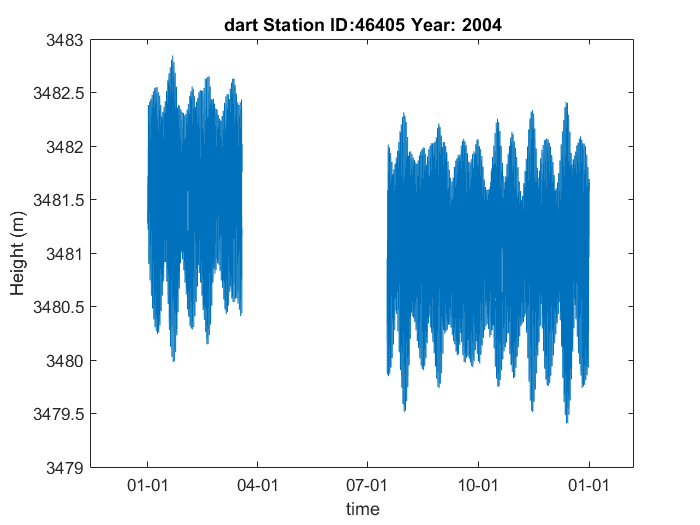

% Checking for url connection and file availability
request = matlab.net.http.RequestMessage;
uri     = matlab.net.URI(location);
r       = send(request,uri);
if strcmp(r.StatusCode,'OK')               % File was found
  localname = [data2,'_',num2str(stationID),'_',num2str(year),'.txt']
  fn       = websave(localname,location);  % downloads the data and saves it in a file
  x        = importdata(fn);
  yyyy = str2double(cell2mat(x.textdata(2:end,1)));    % Year
  mo   = str2double(cell2mat(x.textdata(2:end,2)));    % month
  dd   = str2double(cell2mat(x.textdata(2:end,3)));    % Day
  hh   = str2double(cell2mat(x.textdata(2:end,4)));    % hour
  mi   = str2double(cell2mat(x.textdata(2:end,5)));    % minute
  time = datenum(x.data(:,1:6));                       % Time
  Type = x.data(:,7);                                  % Type = (1, 2, 3 for 15-min, 1-min and 15-sec measurement)
  Height = x.data(:,8);                                % Water column in meteres 
  Height(Height>=9999)=NaN;
  plot(time,Height)
  title([data2,' Station ID:',num2str(stationID),' Year: ',num2str(year)])
  xlabel('time')
  datetick('x','mm-dd','keeplimits')
  ylabel('Height (m)')
else
  disp('Tsunami File does not exist') % File was not found, or site is down or internet is down etc.
end